clc ; clear all ; close all ;
orig_img = imread("D:\IMAGES\ORION\pipp_20240331_003120\_MG_0082\_MG_0047.tif");
disp(size(orig_img));

        3465        5202           3



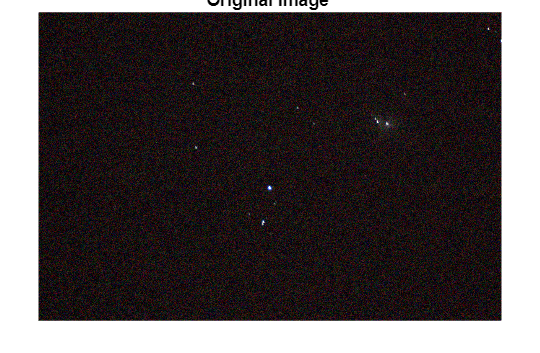

%imshow(orig_img) ; title("Original Image ") ;

rgb_img = orig_img(:, :, 1:3); 
imshow(rgb_img); title("Original Image ") ;

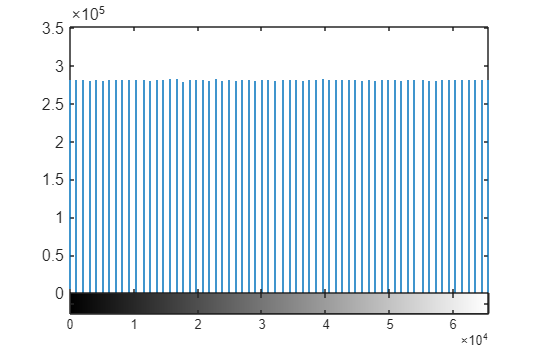

grayimg = im2gray(rgb_img);
gray1img = im2uint16(grayimg) ;

gray2img = histeq(gray1img);
imhist(gray2img);

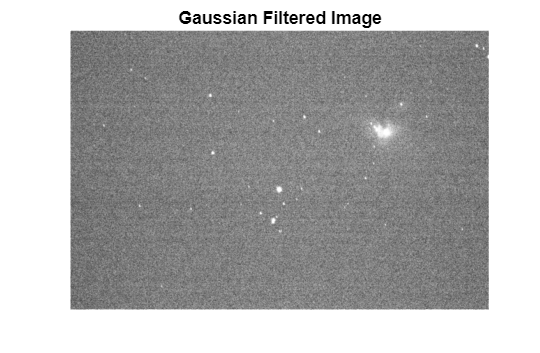

filteredImage = imgaussfilt(gray2img, 6); 
imshow(filteredImage);
title('Gaussian Filtered Image');

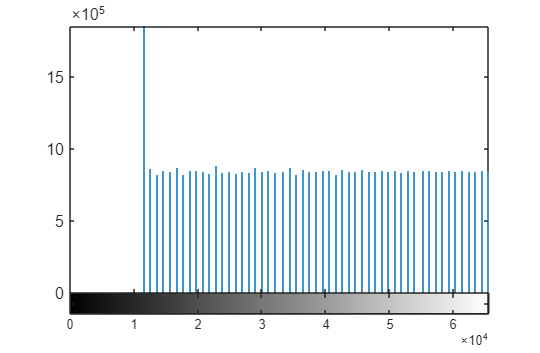

gray3img = histeq(rgb_img);
imhist(gray3img);

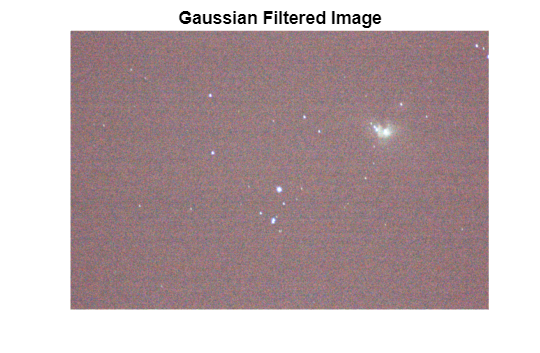

filtered1Image = imgaussfilt(gray3img, 6); 
imshow(filtered1Image);
title('Gaussian Filtered Image');

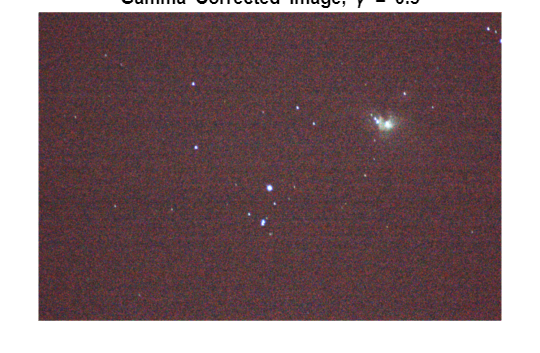

image_double = im2double(filtered1Image);
gamma = 0.5;

% Apply gamma correction to each channel (R, G, B)
corrected_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected_image);
title(['Gamma Corrected Image, \gamma = ', num2str(gamma)]);

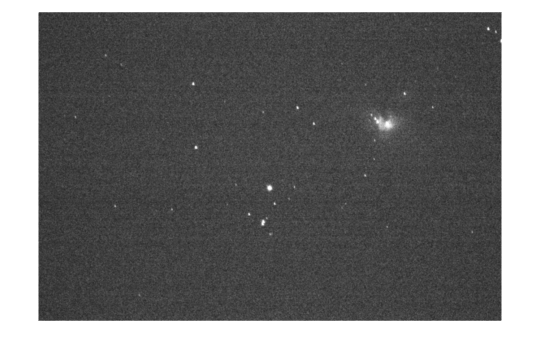

filteredImage = medfilt2(im2gray(corrected_image));
imshow(filteredImage);